% Trying normalization where each factor is normalized by its
% own initial value, then dividing by 2. 

clear all

%% Parameters
tspan = 2014:0.1:2300;
numSim = 500;
hl = 0.0;
diffH = 0.1;
hu = 1.0;

peakTvsHom = tempvshomophily(numSim, tspan, hl, diffH, hu);

homophily = 0


ans =      7     1


Elapsed time is 222.567400 seconds.
homophily = 0.1


ans =      7     1


Elapsed time is 221.785969 seconds.
homophily = 0.2


ans =      7     1


Elapsed time is 221.893780 seconds.
homophily = 0.3


ans =      7     1


Elapsed time is 223.048749 seconds.
homophily = 0.4


ans =      7     1


Elapsed time is 223.268115 seconds.
homophily = 0.5


ans =      7     1


Elapsed time is 222.269042 seconds.
homophily = 0.6


ans =      7     1


Elapsed time is 225.843659 seconds.
homophily = 0.7


ans =      7     1


Elapsed time is 224.290899 seconds.
homophily = 0.8


ans =      7     1


Elapsed time is 226.264129 seconds.
homophily = 0.9


ans =      7     1


Elapsed time is 226.366255 seconds.
homophily = 1


ans =      7     1


Elapsed time is 224.300576 seconds.


clf
peakTvsHom

peakTvsHom = struct with fields:
          upperBound: [2.6945 2.7428 2.7353 2.7431 2.8003 2.8073 2.8708 2.8780 2.9126 2.9660 3.0854]
               IQupp: [2.5158 2.5514 2.5522 2.5744 2.5954 2.6131 2.6435 2.6498 2.6709 2.7297 2.8424]
             median_: [2.4052 2.4285 2.4327 2.4512 2.4670 2.4957 2.5079 2.5386 2.5507 2.5886 2.7099]
               IQlow: [2.2752 2.2946 2.2899 2.3374 2.3437 2.3654 2.3576 2.3995 2.4258 2.4269 2.5388]
          lowerBound: [2.0608 2.0948 2.0526 2.1309 2.1449 2.1553 2.1292 2.1659 2.2244 2.2429 2.2756]
                std_: [0.4399 0.4536 0.4867 0.5751 0.4536 0.4454 0.4562 0.4698 0.4431 0.4416 0.4573]
                avg_: [2.4732 2.5519 2.5654 2.6799 2.7167 2.6515 2.6877 2.7118 2.8050 2.8985 3.2353]
           homophily: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
            maxTtime: [2.0897e+03 2.0902e+03 2.0958e+03 2.0919e+03 2.0917e+03 2094 2.0914e+03 2.1015e+03 2.1041e+03 2.1089e+03 2.1251e+03]
    temperature_vals: [5500×28

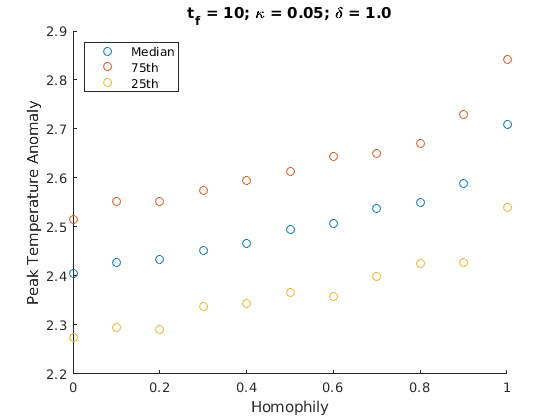

scatter(peakTvsHom.homophily, peakTvsHom.median_,'Marker', 'o')
hold on
scatter(peakTvsHom.homophily, peakTvsHom.IQupp,  'Marker', 'o')
scatter(peakTvsHom.homophily, peakTvsHom.IQlow,  'Marker', 'o')
ylabel("Peak Temperature Anomaly")
xlabel("Homophily")
legend("Median", "75th", "25th",'Location','northwest')
title("t_f = 10; \kappa = 0.05; \delta = 1.0")

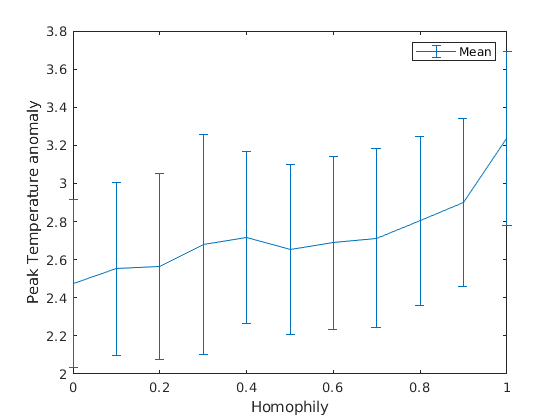

clf
errorbar(0:0.1:1,peakTvsHom.avg_, peakTvsHom.std_)
xlabel("Homophily")
ylabel("Peak Temperature anomaly")
legend("Mean")

peakTvsIneq = tempvsinequality(numSim, tspan)

difference = 0.65


ans =      7     1


Elapsed time is 222.964468 seconds.
difference = 1


ans =      7     1


Elapsed time is 225.548627 seconds.
difference = 1.35


ans =      7     1


Elapsed time is 225.613248 seconds.
difference = 1.15


ans =      7     1


Elapsed time is 223.591107 seconds.
difference = 1.5


ans =      7     1


Elapsed time is 223.852693 seconds.
difference = 1.85


ans =      7     1


Elapsed time is 221.252697 seconds.
difference = 1.65


ans =      7     1


Elapsed time is 222.239132 seconds.
difference = 2


ans =      7     1


Elapsed time is 220.783577 seconds.
difference = 2.35


ans =      7     1


Elapsed time is 219.244270 seconds.


peakTvsIneq = struct with fields:
          upperBound: [2.8439 2.8530 2.8818 2.9090 3.0525 3.1782 3.1871 3.3647 3.3811]
               IQupp: [2.5808 2.6206 2.6607 2.6761 2.8061 2.9753 2.9112 3.1194 3.1999]
             median_: [2.4470 2.4893 2.5409 2.5472 2.6674 2.8728 2.7922 3.0182 3.0787]
               IQlow: [2.3172 2.3501 2.4115 2.4176 2.5336 2.7609 2.6563 2.8984 2.9522]
          lowerBound: [2.0993 2.1355 2.2079 2.2045 2.3490 2.5941 2.4581 2.7154 2.7826]
                std_: [0.3360 0.4235 0.3268 0.4470 0.4601 0.4100 0.4714 0.5071 0.5074]
                avg_: [2.9041 3.0168 2.9352 3.3248 3.3076 3.2013 3.3239 3.4004 3.4623]
          omega_diff: [0.6500 1 1.3500 1.1500 1.5000 1.8500 1.6500 2 2.3500]
         omega_ratio: [0.8556 0.7778 0.7000 0.7700 0.7000 0.6300 0.7000 0.6364 0.5727]
            maxTtime: [2.1114e+03 2.1191e+03 2.1292e+03 2.1138e+03 2.1264e+03 2.1307e+03 2.1173e+03 2.1371e+03 2.1565e+03]
    temperature_vals: [4500×2861 double]


clf
peakTvsIneq

peakTvsIneq = struct with fields:
          upperBound: [2.8439 2.8530 2.8818 2.9090 3.0525 3.1782 3.1871 3.3647 3.3811]
               IQupp: [2.5808 2.6206 2.6607 2.6761 2.8061 2.9753 2.9112 3.1194 3.1999]
             median_: [2.4470 2.4893 2.5409 2.5472 2.6674 2.8728 2.7922 3.0182 3.0787]
               IQlow: [2.3172 2.3501 2.4115 2.4176 2.5336 2.7609 2.6563 2.8984 2.9522]
          lowerBound: [2.0993 2.1355 2.2079 2.2045 2.3490 2.5941 2.4581 2.7154 2.7826]
                std_: [0.3360 0.4235 0.3268 0.4470 0.4601 0.4100 0.4714 0.5071 0.5074]
                avg_: [2.9041 3.0168 2.9352 3.3248 3.3076 3.2013 3.3239 3.4004 3.4623]
          omega_diff: [0.6500 1 1.3500 1.1500 1.5000 1.8500 1.6500 2 2.3500]
         omega_ratio: [0.8556 0.7778 0.7000 0.7700 0.7000 0.6300 0.7000 0.6364 0.5727]
            maxTtime: [2.1114e+03 2.1191e+03 2.1292e+03 2.1138e+03 2.1264e+03 2.1307e+03 2.1173e+03 2.1371e+03 2.1565e+03]
    temperature_vals: [4500×2861 double]


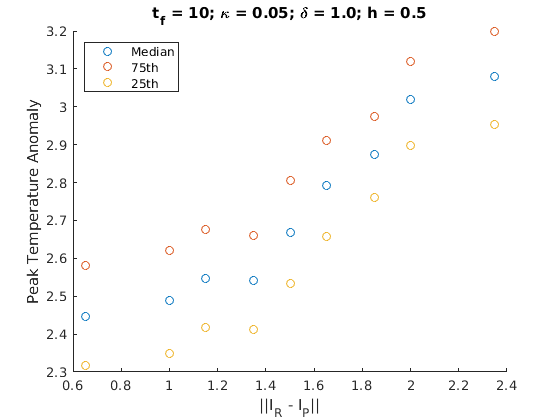

scatter(peakTvsIneq.omega_diff, peakTvsIneq.median_,'Marker', 'o')
hold on
scatter(peakTvsIneq.omega_diff, peakTvsIneq.IQupp,  'Marker', 'o')
scatter(peakTvsIneq.omega_diff, peakTvsIneq.IQlow,  'Marker', 'o')
ylabel("Peak Temperature Anomaly")
xlabel("||I_R - I_P||")
legend("Median", "75th", "25th",'Location','northwest')
title("t_f = 10; \kappa = 0.05; \delta = 1.0; h = 0.5")

clf
peakTvsIneq

peakTvsIneq = struct with fields:
          upperBound: [2.8439 2.8530 2.8818 2.9090 3.0525 3.1782 3.1871 3.3647 3.3811]
               IQupp: [2.5808 2.6206 2.6607 2.6761 2.8061 2.9753 2.9112 3.1194 3.1999]
             median_: [2.4470 2.4893 2.5409 2.5472 2.6674 2.8728 2.7922 3.0182 3.0787]
               IQlow: [2.3172 2.3501 2.4115 2.4176 2.5336 2.7609 2.6563 2.8984 2.9522]
          lowerBound: [2.0993 2.1355 2.2079 2.2045 2.3490 2.5941 2.4581 2.7154 2.7826]
                std_: [0.3360 0.4235 0.3268 0.4470 0.4601 0.4100 0.4714 0.5071 0.5074]
                avg_: [2.9041 3.0168 2.9352 3.3248 3.3076 3.2013 3.3239 3.4004 3.4623]
          omega_diff: [0.6500 1 1.3500 1.1500 1.5000 1.8500 1.6500 2 2.3500]
         omega_ratio: [0.8556 0.7778 0.7000 0.7700 0.7000 0.6300 0.7000 0.6364 0.5727]
            maxTtime: [2.1114e+03 2.1191e+03 2.1292e+03 2.1138e+03 2.1264e+03 2.1307e+03 2.1173e+03 2.1371e+03 2.1565e+03]
    temperature_vals: [4500×2861 double]


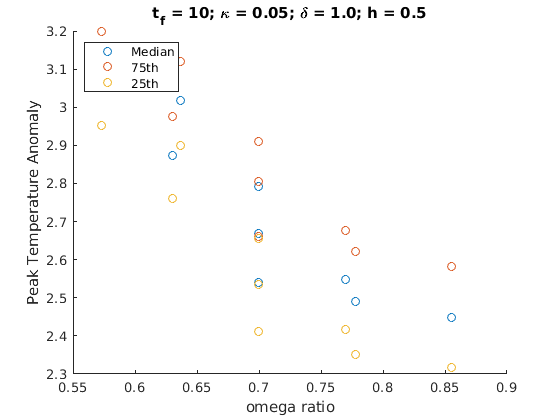

scatter(peakTvsIneq.omega_ratio, peakTvsIneq.median_,'Marker', 'o')
hold on
scatter(peakTvsIneq.omega_ratio, peakTvsIneq.IQupp,  'Marker', 'o')
scatter(peakTvsIneq.omega_ratio, peakTvsIneq.IQlow,  'Marker', 'o')
ylabel("Peak Temperature Anomaly")
xlabel("omega ratio")
legend("Median", "75th", "25th",'Location','northwest')
title("t_f = 10; \kappa = 0.05; \delta = 1.0; h = 0.5")

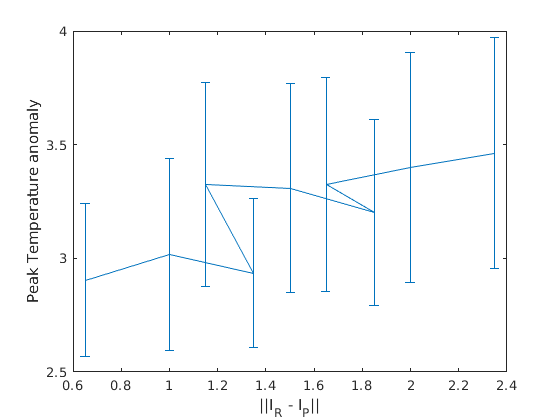

clf
errorbar(peakTvsIneq.omega_diff,peakTvsIneq.avg_, peakTvsIneq.std_)
xlabel("||I_R - I_P||")
ylabel("Peak Temperature anomaly")